## Current/Resistence Response to Frequency

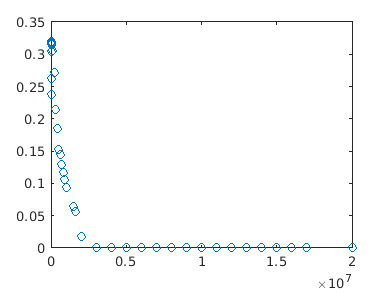

% Ip 
Mhz = 10^6;
Khz = 10^3;
w =       [10       1*Mhz   2*Mhz   3*Mhz   4*Mhz   14*Mhz   17*Mhz     20*Mhz  9*Mhz   100     1*Khz    10*Khz   100*Khz   500*Khz     400*Khz     300*Khz     200*Khz     600*Khz     700*Khz     800*Khz     900*Khz     12*Mhz      5*Mhz       6*Mhz   7*Mhz   8*Mhz   10*Mhz  11*Mhz  12*Mhz  13*Mhz  15*Mhz  16*Mhz  5       4       70      80      90      200     300     800     1.5*Khz     1.5*Mhz     1.6*Mhz];%Hz 
I =       [31.28    18.73   5.89    0.08    0.07    0.22     0.36       0.69    0.11    32.91   32.95   33.01     35.15     22.03       23.29       25.41       30.6        21.08       20.29       19.65       19.12       0.2         0.08        0.09    0.08    0.1     0.09    .11     0.18    0.16    0.21    0.41    27.11   24.44   32.92   32.93   32.94   33      32.98   32.8    32.97       16.79       15.43];%mA
v_y =     [125      379     700     1030    1330    4220     4340       3600    1570    109     109     110       130       223         189.5       162.3       139.1       250.5       277         313.6       342.1       3970        1668        2010    2344    2721    3465    3761    3975    4136    4342    4384    109     109     109.5   109.5   109.5   110.2   110.2   109.5   109.6       533         564]; %mV - Green
v_x =     [103      199     334     470     615     2950     3340       3780    3140    103     103     105       115       145         125.9       118.2       112.6       145.7       156.8       168.5       180.9       2630        788         959     1145    1313    1970    2319    2633    2825    3000    3096    103     103     104     104     104     103.8   104.1   103.9   103.2       263         275]; %mV - Yellow 
v_WG = 5;%v

figure
%plot(I,v_x,'o')
plot( w,I./v_x, 'o')

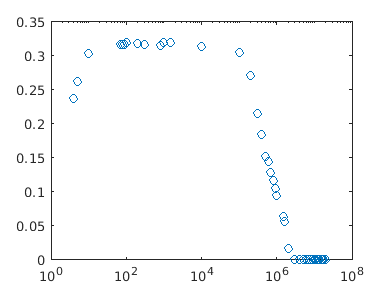

figure
semilogx(w,I./v_x, 'o')

## Pure Measurements

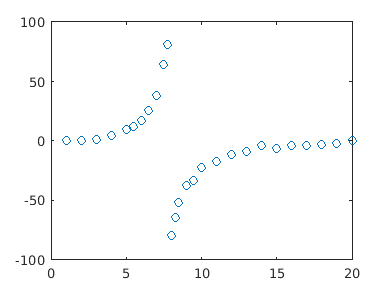

% Ih

B_1 = 300; %T \pm 4

w_h   = [ 1*Mhz   2*Mhz     3*Mhz   4*Mhz   5*Mhz   5.5*Mhz   6*Mhz   6.5*Mhz   7*Mhz   7.5*Mhz   7.75*Mhz  8*Mhz   8.25*Mhz   8.5*Mhz   9*Mhz   9.5*Mhz   10*Mhz  11*Mhz  12*Mhz  13*Mhz  14*Mhz  15*Mhz  16*Mhz  17*Mhz  18*Mhz  19*Mhz  20*Mhz]./Mhz;
v_p   = [ 2.185   2.49      3.03    3.45    3.83    3.937     4.06    4.028     3.73    3.297     3.136     3.136   3.297      3.557     4.053   4.364      4.62    4.985   5.27    5.475   5.555   5.643   5.663   5.628   5.586   5.467   5.415]; %x [v]
v_h   = [ 1.011   1.25      1.73    2.28    3.16    3.779     4.643   5.827     7.23    8.25      8.44      8.16    7.41       6.596     5.387   4.631      3.877   2.82    2.247   1.847   1.491   1.28    1.134   1.013   0.917   0.851   0.798]; %y [v]
phase = [ 0       0         1       5       10      12        17      26        38      64        81        101     116        128       143     147        158     163     169     171     176     174     176     176     177     178     180]; %deg 
phase_fixed = cat(2,phase(phase<=90),phase(phase>90)-180);
figure
plot(w_h,phase_fixed,"o")

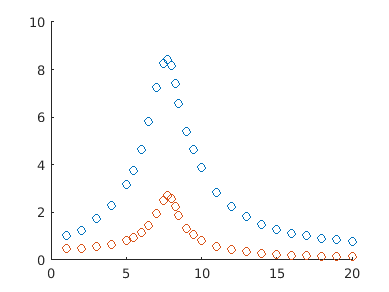

figure
hold on;
v_h_tilde = v_h./v_p;
plot(w_h,v_h ,"o")
plot(w_h,v_h_tilde ,"o")

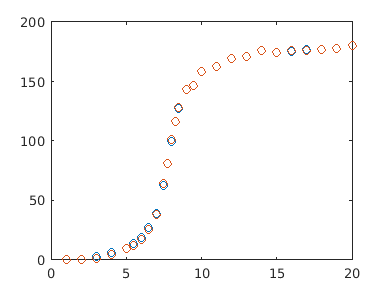


B_2 = 150; %mT \pm 4

w_h_2   = [ 1*Mhz   2*Mhz   3*Mhz   4*Mhz   5*Mhz   5.5*Mhz   6*Mhz   6.5*Mhz   7*Mhz   7.5*Mhz   8*Mhz   8.5*Mhz   9*Mhz   10*Mhz  11*Mhz  12*Mhz  13*Mhz  14*Mhz  15*Mhz  16*Mhz  17*Mhz  18*Mhz  ]./Mhz;
v_p_2   = [ 2.232   2.58    3.011   3.42    3.799   3.920     4.055   4.034     3.81    3.337     3.136   3.538     4.04    4.59    5.005   5.256   5.469   5.543   5.643   5.663   5.628   5.583   ];
v_h_2   = [ 1.042   1.303   1.719   2.294   3.162   3.776     4.658   5.771     7.196   8.31      8.2     6.8       5.462   3.86    2.82    2.244   1.841   1.49    1.297   1.126   1.005   0.909   ];
phase_2 = [ 0       0       3       6.5     10      14        19      27        39      63        99.5    127       143     158     163     169     171     176     174     175.5   177     177     ]; %deg 

figure
plot(w_h_2,phase_2, 'o')
hold on
plot(w_h,phase, 'o')

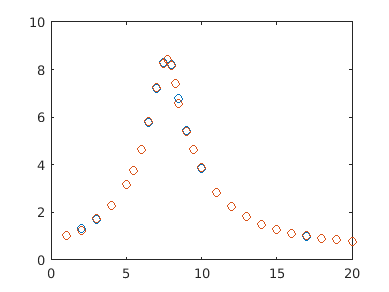

figure
plot(w_h_2,v_h_2, 'o')
hold on
plot(w_h,v_h, 'o')

## Amplitude Fits

[xData, yData] = prepareCurveData( w_h, v_h_tilde );

% Sigma Model
sigma_model_ft = fittype( 'sigma0/sqrt(4*tau^2*(2*pi*f)^2+(1+tau^2*((2*pi*f0)^2-(2*pi*f)^2))^2)', 'independent', 'f', 'dependent', 'sigma' );
sigma_model_opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
sigma_model_opts.Display = 'Off';
sigma_model_opts.Lower = [0 0 0];
sigma_model_opts.StartPoint = [7.9 0.00463422413406744 1.32];
[sigma_model_fr, sigma_model_gof] = fit( xData, yData, sigma_model_ft, sigma_model_opts)

sigma_model_fr =      General model:
     sigma_model_fr(f) = sigma0/sqrt(4*tau^2*(2*pi*f)^2+(1+tau^2*((2*pi*f0)^2-
                    (2*pi*f)^2))^2)
     Coefficients (with 95% confidence bounds):
       f0 =       7.823  (7.794, 7.852)
       sigma0 =       55.34  (52.19, 58.49)
       tau =      0.2101  (0.2014, 0.2187)

sigma_model_gof = struct with fields:
           sse: 0.0428
       rsquare: 0.9976
           dfe: 24
    adjrsquare: 0.9974
          rmse: 0.0422



sigma_model_v_h_fit = sigma_model_fr.sigma0./sqrt(4*sigma_model_fr.tau.^2*(2*pi*w_h).^2+(1+sigma_model_fr.tau.^2*((2*pi*sigma_model_fr.f0).^2-(2*pi*w_h).^2)).^2);
[sigma_model_R,sigma_model_p] = corrcoef(v_h_tilde,sigma_model_v_h_fit)

sigma_model_R =     1.0000    0.9990
    0.9990    1.0000


sigma_model_p =     1.0000    0.0000
    0.0000    1.0000



% Harmonic Oscillator Model
ho_model_ft = fittype( 'A/(2*pi*f*(sqrt((2*(2*pi*f0)*Xi)^2+1/(2*pi*f)^2*((2*pi*f0)^2-(2*pi*f)^2)^2)))', 'independent', 'f', 'dependent', 'v_h' );
ho_model_opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
ho_model_opts.Display = 'Off';
ho_model_opts.Lower = [0 0 0];
ho_model_opts.StartPoint = [0.0461713906311539 0.800068480224308 7.9];
[ho_model_fr, gof] = fit( xData, yData, ho_model_ft, ho_model_opts )

ho_model_fr =      General model:
     ho_model_fr(f) = A/(2*pi*f*(sqrt((2*(2*pi*f0)*Xi)^2+1/(2*pi*f)^2*((2*pi*f0)
                    ^2-(2*pi*f)^2)^2)))
     Coefficients (with 95% confidence bounds):
       A =        1254  (1216, 1292)
       Xi =     0.09639  (0.09248, 0.1003)
       f0 =        7.86  (7.831, 7.889)

gof = struct with fields:
           sse: 0.0428
       rsquare: 0.9976
           dfe: 24
    adjrsquare: 0.9974
          rmse: 0.0422



ho_model_v_h_fit = ho_model_fr.A./(2*pi.*w_h.*(sqrt((2*(2*pi*ho_model_fr.f0)*ho_model_fr.Xi).^2+1./(2*pi.*w_h).^2.*((2*pi*ho_model_fr.f0).^2-(2*pi.*w_h).^2).^2)));
[ho_model_R,ho_model_p] = corrcoef(v_h_tilde,ho_model_v_h_fit)

ho_model_R =     1.0000    0.9990
    0.9990    1.0000


ho_model_p =     1.0000    0.0000
    0.0000    1.0000


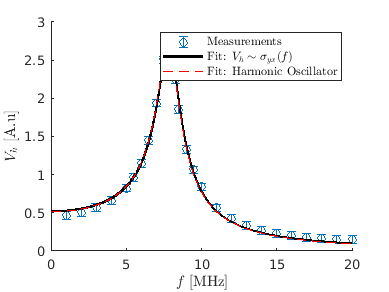


f_plot = linspace(0.001,20,10000);
ho_model_v_h_plot = ho_model_fr.A./(2*pi.*f_plot.*(sqrt((2*(2*pi*ho_model_fr.f0)*ho_model_fr.Xi).^2+1./(2*pi.*f_plot).^2.*((2*pi*ho_model_fr.f0).^2-(2*pi.*f_plot).^2).^2)));
sigma_model_v_h_plot = sigma_model_fr.sigma0./sqrt(4*sigma_model_fr.tau.^2*(2*pi.*f_plot).^2+(1+sigma_model_fr.tau.^2*((2*pi*sigma_model_fr.f0).^2-(2*pi.*f_plot).^2)).^2);

% Plot fit with data.
figure();
hold on;
errorbar(w_h, v_h_tilde, 0.05*ones(size(w_h)), 'o');
plot(f_plot, sigma_model_v_h_plot, 'black', 'LineWidth',2)
plot(f_plot, ho_model_v_h_plot, 'r--')
legend( ...
    'Measurements', ...
    'Fit: $V_h \sim \sigma_{yx}(f)$', ...
    'Fit: Harmonic Oscillator', ...
    'Location', 'NorthEast', ...
    'Interpreter', 'latex' ...
);
% Label axes
xlabel('$f$ [MHz]', 'Interpreter', 'latex' );
ylabel('$V_h$ [A.u]', 'Interpreter', 'latex' );

## Phase fits

figure;
hold on;
errorbar(w_h, phase_fixed, 1.5*ones(size(w_h)), 1.5*ones(size(w_h)), '.');

[xData, yData] = prepareCurveData(w_h, phase_fixed);

% Set up fittype and options.
ho_model_ft = fittype( '180/pi*atan(2*f*f0*Xi/(f^2-f0^2))', 'independent', 'f', 'dependent', 'y' );
ho_model_opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
ho_model_opts.Display = 'Off';
ho_model_opts.StartPoint = [0.09639 -7.9];
[ho_model_ft, gof] = fit(xData, yData, ho_model_ft, ho_model_opts)

ho_model_ft =      General model:
     ho_model_ft(f) = 180/pi*atan(2*f*f0*Xi/(f^2-f0^2))
     Coefficients (with 95% confidence bounds):
       Xi =     0.09383  (0.08724, 0.1004)
       f0 =      -7.875  (-7.912, -7.839)

gof = struct with fields:
           sse: 184.1788
       rsquare: 0.9938
           dfe: 25
    adjrsquare: 0.9935
          rmse: 2.7142



ho_model_phase_fit = 180/pi*atan(2*w_h*ho_model_ft.f0*ho_model_ft.Xi./(w_h.^2-ho_model_ft.f0^2));
[ho_model_R,ho_model_p] = corrcoef(phase_fixed,ho_model_phase_fit)

ho_model_R =     1.0000    0.9969
    0.9969    1.0000


ho_model_p =     1.0000    0.0000
    0.0000    1.0000



sigma_model_ft = fittype( '180/pi*atan(2*f*tau/(1+tau^2*(f0^2-f^2)))', 'independent', 'f', 'dependent', 'y' );
sigma_model_opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
sigma_model_opts.Display = 'Off';
sigma_model_opts.Lower = [-Inf 0];
sigma_model_opts.StartPoint = [-7.9 1.32];
[sigma_model_fr, gof] = fit(xData, yData, sigma_model_ft, sigma_model_opts)

sigma_model_fr =      General model:
     sigma_model_fr(f) = 180/pi*atan(2*f*tau/(1+tau^2*(f0^2-f^2)))
     Coefficients (with 95% confidence bounds):
       f0 =      -7.841  (-7.878, -7.803)
       tau =       1.353  (1.259, 1.448)

gof = struct with fields:
           sse: 184.1788
       rsquare: 0.9938
           dfe: 25
    adjrsquare: 0.9935
          rmse: 2.7142



sigma_model_phase_fit = 180/pi*atan(2*w_h*sigma_model_fr.tau./(1+sigma_model_fr.tau^2*(sigma_model_fr.f0^2-w_h.^2)));
[sigma_model_R,sigma_model_p] = corrcoef(phase_fixed,sigma_model_phase_fit)

sigma_model_R =     1.0000    0.9969
    0.9969    1.0000


sigma_model_p =     1.0000    0.0000
    0.0000    1.0000


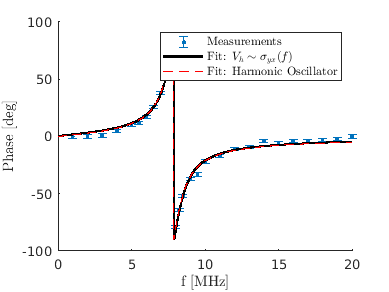


f_plot = linspace(0.001,20,10000);
sigma_model_phase_plot = 180/pi*atan(2*f_plot*sigma_model_fr.tau./(1+sigma_model_fr.tau^2*(sigma_model_fr.f0^2-f_plot.^2)));
plot(f_plot, sigma_model_phase_plot, 'black', 'LineWidth',2)
ho_model_phase_plot = 180/pi*atan(2*f_plot*ho_model_ft.f0*ho_model_ft.Xi./(f_plot.^2-ho_model_ft.f0^2));
plot(f_plot, ho_model_phase_plot, 'r--')

legend( ...
    'Measurements', ...
    'Fit: $V_h \sim \sigma_{yx}(f)$', ...
    'Fit: Harmonic Oscillator', ...
    'Location', 'NorthEast', ...
    'Interpreter', 'latex' ...
);
xlabel('f [MHz]', 'Interpreter', 'latex' );
ylabel('Phase [deg]', 'Interpreter', 'latex' );